# **Benchmark Path Planners for Differential Drive Robots in Warehouse Map**

This example shows how to choose the best 2-D path planner for a differential drive robot in a warehouse environment from the available path planners. Use the `plannerBenchmark` object to benchmark the path planners `plannerRRT`, `plannerRRTStar`, `plannerBiRRT`, `plannerPRM`, and `plannerHybridAstar` on the warehouse environment with the randomly chosen start and goal poses. Compare the path planners based on their ability to find a valid path, clearance from the obstacles, time taken to initialize a planner, time taken to find a path, length of the path, and smoothness of the path. A suitable planner is chosen based on the performance of each path planner on the above mentioned metrics.

## Set Up Environment

Create a `binaryOccupancyMap` object from a warehouse map. In the warehouse, the mobile robot moves from the loading station to the unloading station to place the goods.

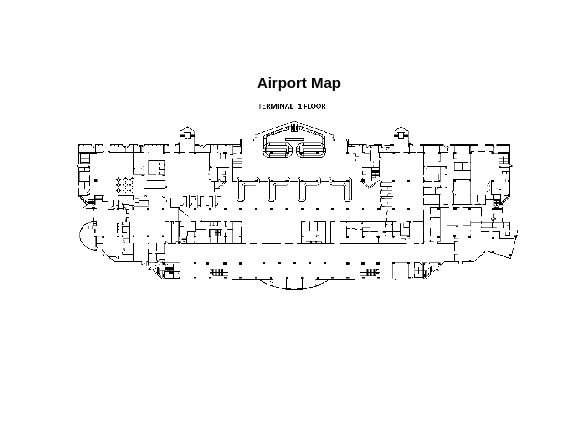

imageL = imread('terminal_floor_editied.pgm');
imshow(imageL)
title('Airport Map')

imageBW = imageL(:,:) < 100;
%imshow(imageBW)
%title('Airport Map Black and White')
map = binaryOccupancyMap(imageBW);

Visualize the map.

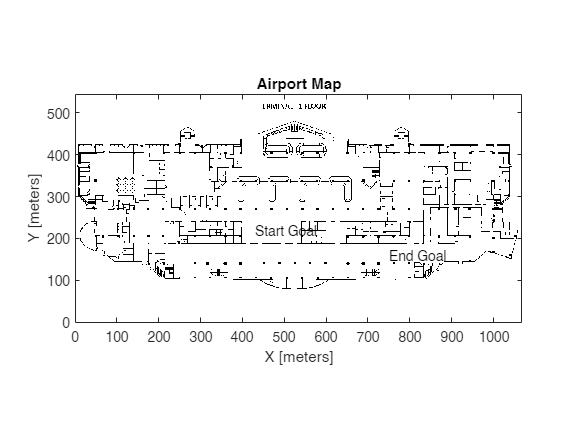

figure
show(map)
title("Airport Map")
startGoalTextLoc = [430 220 0];
endGoalTextLoc = [750 160 0];
hold on
text(startGoalTextLoc(1),startGoalTextLoc(2),1,"Start Goal");
text(endGoalTextLoc(1),endGoalTextLoc(2),1,"End Goal");
hold off

## **Define Environment and Planners for Benchmarking**

Specify the minimum turning radius for the differential drive robot.

minTurningRadius = 2; % meters

Create a `stateSpaceDubins` object with the state space bounds to be the same as map limits. set the minimum turing radius.

stateSpace = stateSpaceDubins([map.XWorldLimits; map.YWorldLimits; [-2*pi 2*pi]]);
stateSpace.MinTurningRadius = minTurningRadius;

Create a `validatorOccupancyMap` state validator with the Dubins state space using the map. Specify the distance for interpolating and validating path segments.

validator = validatorOccupancyMap(stateSpace,Map=map);
validator.ValidationDistance = 0.01*(1/map.Resolution); % meters

Define the function handles for the initialization functions of each planners. For more information on these initialization functions, see Initialization Functions for Planners.

rrtInit = @(validator) plannerRRTWrapper(validator);
rrtStarInit = @(validator) plannerRRTStarWrapper(validator);
birrtInit = @(validator) plannerBiRRTWrapper(validator);
haStarInit = @(validator) plannerHybridAStarWrapper(validator,minTurningRadius);
prmInit = @(validator) plannerPRM(validator.StateSpace,validator);

Define the function handle for the plan function, which is common for all the planners.

planFcn = @(initOutput,start,goal) plan(initOutput,start,goal);

## Randomly Select Start-Goal Pairs on Warehouse Map

The start and goal locations are randomly sampled from the loading and unloading station area, respectively. Specify the number of start-goal pairs that must be randomly generated. In this example only three start-goal pair are chosen to reduce the execution time of this example. Increase the start-goal pair number to get sufficient map coverage.

% Set default random number for repeatability of results.
rng("default")
% Select the number of start-goal pairs.
numStartGoalPairs = 3;

The start location of the robot is sampled from the rectangle area marked as loading station and goal location is sampled from the rectangle area marked as unloading station area. Robot locations are sampled uniformly in the marked area. The rectangle area is specified as a vector of form `[x y w h].` `x` and `y` specify the coordinate of the bottom left corner of the rectangle. `w` and `h` specify the width and height of the rectangle.

startPos = [430 220 20 20];
startLocations = helperSampleSelectedAreaOnMap(validator,startPos,numStartGoalPairs);

endPos = [750 160 25 25];
goalLocations = helperSampleSelectedAreaOnMap(validator,endPos,numStartGoalPairs);


Visualize the map with all the randomly sampled start and goal locations.

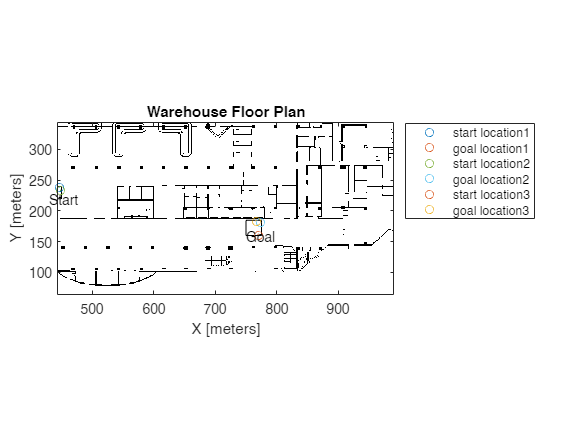

show(map)
title("Warehouse Floor Plan")
% Indicate the loading and unloading station on the map.
hold on
text(startGoalTextLoc(1),startGoalTextLoc(2),1,"Start");
rectangle(Position=startPos)

text(endGoalTextLoc(1),endGoalTextLoc(2),1,"Goal");
rectangle(Position=endPos)

% Set the length of the line representing the pose in the start-goal visualization.
r = 2;

% Display all the start-goal pairs on the map.
for i=1:numStartGoalPairs
    start = startLocations(i,:);
    goal = goalLocations(i,:);
    
    % Define the legend displayed on the map    
    startString = strcat("start location",num2str(i));
    goalString = strcat("goal location",num2str(i));
    % Display start and goal location of robot.
    p1 = plot(start(1,1),start(1,2),"o",DisplayName=startString);
    c1 = p1.Color;
    p2 = plot(goal(1,1),goal(1,2),"o",DisplayName=goalString);
    c2 = p2.Color;
    % Display start and goal headings.
    plot([start(1) start(1)+r*cos(start(3))],[start(2) start(2)+r*sin(start(3))],...
         "-",Color=c1,HandleVisibility="off")
    plot([goal(1) goal(1)+r*cos(goal(3))],[goal(2) goal(2)+r*sin(goal(3))],...
         "-",Color=c2,HandleVisibility="off")
        
end
hold off
legend(Location="northeastoutside")

## Planner Benchmark Object Creation and Running Benchmark

Create a `plannerBenchmark` object for each start-goal pair and add the planners for benchmarking. The planner are executed twice on the same environment and start-goal pair by setting the `runCount` value to `2`. This ensures the metrics results are accurate since sampling based planners like `plannerRRT`, `plannerRRTStar`, `plannerBiRRT`, and `plannerPRM` produce different output on the same set of start-goal pair. In this example `runCount` value is set to `2` to reduce the execution time of this example. Increase the `runCount` value to get more accurate benchmark results.

% To store the generated benchmark objects for each start-goal pair.
benchmarkList = cell(1,numStartGoalPairs);
% Specify the number of times each planner to be executed on the same
% set of start-goal pair.
runCount = 2;

for i=1:size(startLocations,1)
    % Get each start and goal location from all the sampled locations.
    start = startLocations(i,:);
    goal = goalLocations(i,:);

    % Set default random number for repeatability of results.
    rng("default")
    % Construct benchmark object.
    benchmark = plannerBenchmark(validator,start,goal);
    % Add planners for benchmarking using initialization and plan function
    % handles. Additional optional input NumPlanOutput define the number of
    % outputs returned from the plan function.
    addPlanner(benchmark,planFcn,rrtInit,PlannerName="rrt",NumPlanOutput=2)
    addPlanner(benchmark,planFcn,rrtStarInit,PlannerName="rrtStar",NumPlanOutput=2)
    addPlanner(benchmark,planFcn,birrtInit,PlannerName="biRRT",NumPlanOutput=2)
    addPlanner(benchmark,planFcn,prmInit,PlannerName="plannerPRM",NumPlanOutput=2)
    %addPlanner(benchmark,planFcn,haStarInit,PlannerName="hybriadAstar",NumPlanOutput=2)
    % Run the benchmark.
    runPlanner(benchmark,runCount)
    % Store the benchmark for further analysis.
    benchmarkList{i} = benchmark;
end

Initializing rrt ...
Done.
Planning a path from the start pose (446.2945 238.2675 1.2229) to the goal pose (769.8052 160.8928 1.8516) using rrt.
Executing run 1.
Executing run 2.
Initializing rrtStar ...
Done.
Planning a path from the start pose (446.2945 238.2675 1.2229) to the goal pose (769.8052 160.8928 1.8516) using rrtStar.
Executing run 1.
Executing run 2.
Initializing biRRT ...
Done.
Planning a path from the start pose (446.2945 238.2675 1.2229) to the goal pose (769.8052 160.8928 1.8516) using biRRT.
Executing run 1.
Executing run 2.
Initializing plannerPRM ...
Done.
Planning a path from the start pose (446.2945 238.2675 1.2229) to the goal pose (769.8052 160.8928 1.8516) using plannerPRM.
Executing run 1.
Executing run 2.
Initializing rrt ...
Done.
Planning a path from the start pose (448.1158 232.6472 1.6444) to the goal pose (773.9873 181.2282 1.9757) using rrt.
Executing run 1.
Executing run 2.
Initializing rrtStar ...
Done.
Planning a path from the start pose (448.1158 23

## Average Metrics Across all Start-Goal Pairs

All the planner are executed `runCount` times for each start-goal pair. Also all the planners are executed for all the start-goal pairs. This means that all planners are executed `runCount*numStartGoalPairs` times. The plots and tables below show the average metric value across all the start-goal pairs. The tables represent the Mean, Median, and Standard Deviation of each metric averaged across all the start-goal pairs.

The `clearance` metric represent the minimum distance of the path from the obstacles in the environment. The plot shows that `plannerPRM` has the highest clearance.

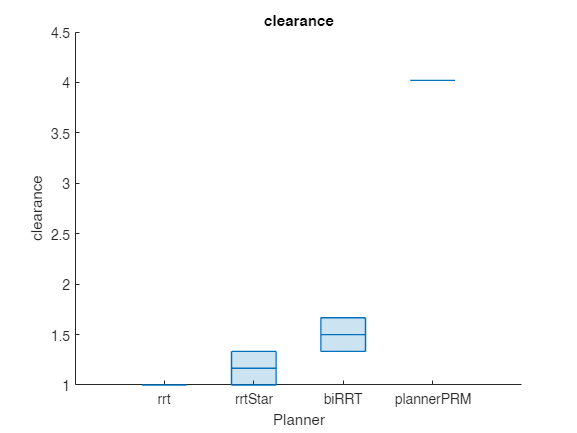

helperPlotAveragedMetrics(benchmarkList,runCount,"clearance")

clearanceAverage = helperCalculateAverageMetricTable(benchmarkList,"clearance")

clearanceAverage = 4×3 table
                   Mean     Median    stdDev 
                  ______    ______    _______

    rrt                1       1            0
    rrtStar       1.1667       1       0.2357
    biRRT            1.5     1.5      0.40825
    plannerPRM    4.0208       4       3.2914


The `isPathValid` metric represent the sucess rate of each planner expressed in percentage. The plot shows that all the path planners produced valid path for all the start-goal pairs.

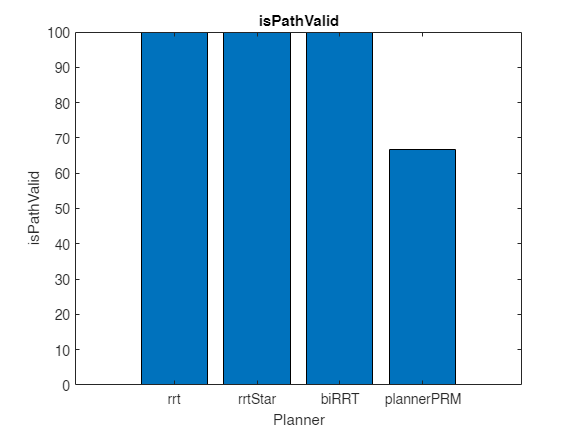

helperPlotAveragedMetrics(benchmarkList,runCount,"isPathValid")

isPathValidAverage = helperCalculateAverageMetricTable(benchmarkList,"isPathValid")

isPathValidAverage = 4×3 table
                   Mean     Median    stdDev
                  ______    ______    ______

    rrt              100     100          0 
    rrtStar          100     100          0 
    biRRT            100     100          0 
    plannerPRM    66.667     100      47.14 


The `executionTime` metric represent the time taken by the plan function to execute. The plot shows that `plannerPRM` took the least time, followed by `plannerBiRRT`. We could also note that `plannerRRTStar` took lesser time than `plannerRRT`, this could be due to the lesser number of start-goal pairs used for benchmarking.

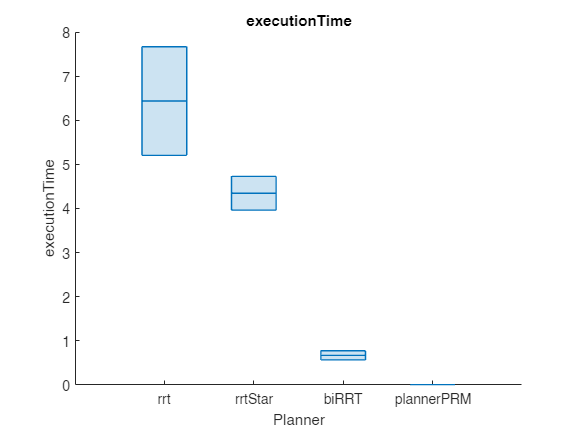

helperPlotAveragedMetrics(benchmarkList,runCount,"executionTime")

execTimeAverage = helperCalculateAverageMetricTable(benchmarkList,"executionTime")

execTimeAverage = 4×3 table
                    Mean        Median      stdDev  
                  _________    ________    _________

    rrt              6.4352      6.8003      0.56178
    rrtStar          4.3466      4.5847      0.82437
    biRRT           0.67238     0.58017      0.14934
    plannerPRM    0.0088212    0.006972    0.0041267


The `initializationTime` metric indicate the time taken to execute the initialization function of each planner. Hence total execution time is the sum of plan function execution time and initialization time. `plannerPRM` has the longest initialization time. Hence `plannerBiRRT` took the least total execution time.

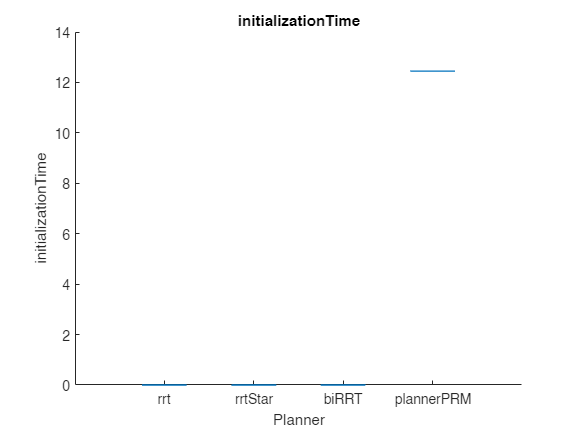

helperPlotAveragedMetrics(benchmarkList,runCount,"initializationTime")

initTimeAverage = helperCalculateAverageMetricTable(benchmarkList,"initializationTime")

initTimeAverage = 4×3 table
                    Mean        Median       stdDev  
                  _________    ________    __________

    rrt           0.0015123    0.001494    0.00024081
    rrtStar       0.0014233     0.00141    6.1959e-05
    biRRT         0.0011343    0.001123    5.6097e-05
    plannerPRM       12.447      12.919        1.1426


The `pathLength` metric represent the length of the generated path. `plannerHybridAstar` has the shortest path, followed by `plannerBiRRT`.

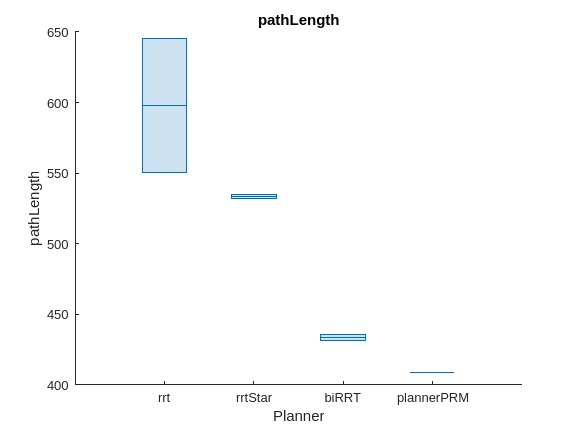

helperPlotAveragedMetrics(benchmarkList,runCount,"pathLength")

pathLengthAverage = helperCalculateAverageMetricTable(benchmarkList,"pathLength")

pathLengthAverage = 4×3 table
                   Mean     Median    stdDev
                  ______    ______    ______

    rrt           598.09    623.08     53.08
    rrtStar       533.51    508.97    34.964
    biRRT         433.92    445.77    32.728
    plannerPRM    408.61    422.62    328.06


The `smoothness` metric represent the smoothness of the path for all poses. `plannerBiRRT` produced the smoothest path (lower smoothness value indicate smoother path) followed by `plannerPRM`. Observe that `plannerRRTStar` produced considerably smoother path compared to `plannerRRT`.

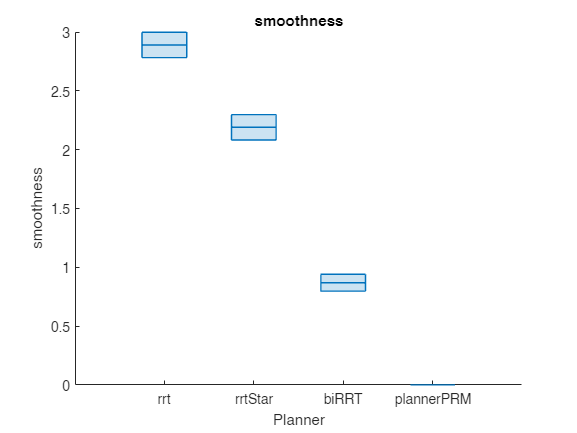

helperPlotAveragedMetrics(benchmarkList,runCount,"smoothness")

smoothnessAverage = helperCalculateAverageMetricTable(benchmarkList,"smoothness")

smoothnessAverage = 4×3 table
                     Mean         Median        stdDev  
                  __________    __________    __________

    rrt               2.8898        2.7945       0.27356
    rrtStar             2.19        2.1612       0.13437
    biRRT            0.86928       0.90551       0.11163
    plannerPRM    0.00071857    0.00080312    0.00055541


If the slightly longer path is not a concern then consider using `plannerBiRRT` for path planning in a warehouse map setup as shown in this example, since it has the smoothest path and lesser execution time. If the path travelled by the robot should be the least then `plannerHybridAstar` could be considered.

As it can be seen, the inconsistency in execution time like, `plannerRRTStar` taking lesser time than `plannerRRT`, increasing the number of start-goal pairs and `runCount` to a considerably larger value will produce more accurate metrics results and better judgement of which path planner to choose.   

## Visualize Metric Results for Specific Start-Goal Pair

The above tables and graphs showed the metric results averaged across all the start-goal pairs. `plannerBiRRT` produced smoother path overall but the path length was slightly longer than `plannerHybridAstar,` which produced the least path length. Probe the start-goal pairs to see which produced the longest path length for `plannerBiRRT`.

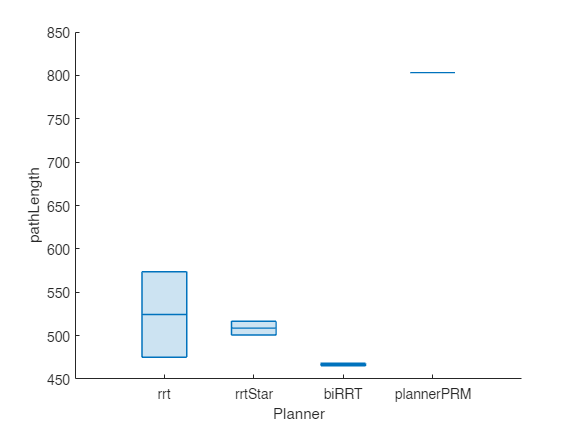

pathLengthMean = zeros(1,numStartGoalPairs);
% Iterate over all the benchmarks and store the mean path length for each
% start-goal pair.
for i=1:numStartGoalPairs
    benchmark = benchmarkList{i};
    pathLengthTable= benchmark.metric("pathLength");
    pathLengthMean(i) = pathLengthTable.Mean("biRRT"); 
end
% Find the index of the benchmark which produced largest mean path length
% value for plannerBiRRT.
[~,largestPathLengthIdx] = max(pathLengthMean);
benchmarkLargestPathlength = benchmarkList{largestPathLengthIdx};

show(benchmarkLargestPathlength,"pathLength")

pathLength = metric(benchmarkLargestPathlength,"pathLength")

pathLength = 4×4 table
                   Mean     Median    StdDev    sampleSize
                  ______    ______    ______    __________

    rrt           524.29    524.29    49.286        2     
    rrtStar       508.61    508.61    7.9206        2     
    biRRT         466.75    466.75    1.5458        2     
    plannerPRM    803.21    803.21         0        2     


## Visualize Path From All Planners for Specific Start-Goal Pair

Visualize the path output from all the planners for the start-goal pair that produced the longest path length for `plannerBiRRT`.

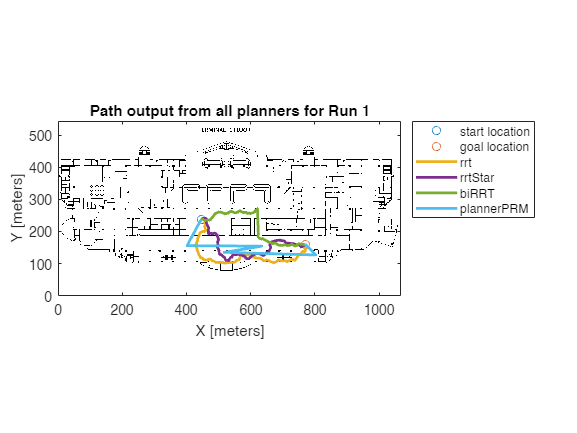

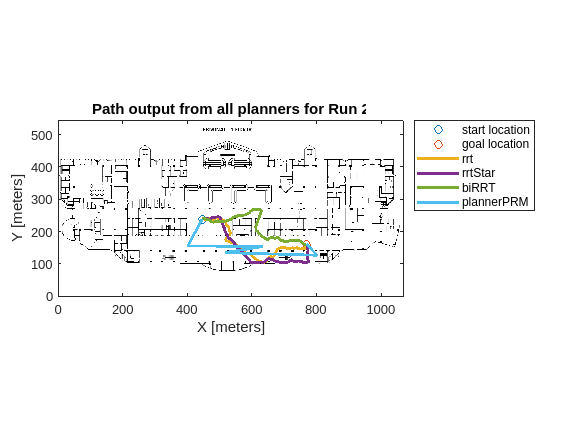

% Retrieve the start and goal location from the benchmark object.
start = benchmarkLargestPathlength.Start;
goal = benchmarkLargestPathlength.Goal;

% Display the path from start location to goal location for all the path
% planners for all the runs in runCount.
for run=1:runCount
    figure
    show(map)
    title(['Path output from all planners for Run ' num2str(run)])
    hold on

    % show start and goal positions of robot.
    plot(start(1,1),start(1,2),"o")
    plot(goal(1,1),goal(1,2),"o")
    % Find the planner names used for benchmarking.
    plannerNames = fieldnames(benchmarkLargestPathlength.PlannerOutput);
    numPlanners = length(plannerNames);
    runString = strcat("Run",num2str(run));
    % Iterate and plot path of each planner for the specified run.
    for i=1:numPlanners
        plannerName = plannerNames{i};
        plannerOutput = benchmarkLargestPathlength.PlannerOutput.(plannerName).PlanOutput.(runString);
        pathObj = plannerOutput{1};
        plot(pathObj.States(:,1),pathObj.States(:,2),"-","LineWidth",2)
    end
    % Specify the legends.
    labels = [{"start location","goal location"} plannerNames'];
    legend(labels,location="northeastoutside")  
    hold off
end

## **Initialization Functions for Planners**

Initialization function for `plannerHybridAStar`.

function planner = plannerHybridAStarWrapper(validator,minTurningRadius)
    map = validator.Map;
    ss = stateSpaceSE2;
    sv = validatorOccupancyMap(ss,Map=map);
    sv.ValidationDistance = validator.ValidationDistance;
    planner = plannerHybridAStar(sv,MinTurningRadius=minTurningRadius);
end

Initialization function for `plannerBiRRT`.

function planner = plannerBiRRTWrapper(sv)
    planner = plannerBiRRT(sv.StateSpace,sv);
    planner.EnableConnectHeuristic = true;
    planner.MaxIterations = 5e4;
    planner.MaxNumTreeNodes = 5e4;
    planner.MaxConnectionDistance = 5;
end

Initialization function for `plannerRRTStar`.

function planner = plannerRRTStarWrapper(sv)
    planner = plannerRRTStar(sv.StateSpace,sv);
    planner.MaxIterations = 5e5;
    planner.MaxNumTreeNodes = 5e5;
    planner.MaxConnectionDistance = 3.8;
end

Initialization function for `plannerRRT`.

function planner = plannerRRTWrapper(sv)
    planner = plannerRRT(sv.StateSpace,sv);
    planner.MaxIterations = 5e5;
    planner.MaxNumTreeNodes = 5e5;
    planner.MaxConnectionDistance = 3.8;
end

*Copyright 2021-2022 The MathWorks, Inc.*